First get the firing rate in different zones

Look at changes in zone preference between habituation and exintcion

SaveFolder = '/media/DataMOBsRAIDN/ProjectEmbReact/Figures/SpikeAnalysis/PFCNeurons_UMazeSpatialFiring/';
cd(SaveFolder)
load('Firing_Ext_NewRandomisation.mat')
EpochFRTemp=EpochFR;
load('Firing_Hab_NewRandomisation.mat')
for k=1:7
    EpochFR{k,2}=EpochFRTemp{k};
end


FR{1,1}=[];
FR{2,2}=[];
FR{2,1}=[];
FR{1,2}=[];
for mouse_num=1:7
    for sp=1:length(EpochFR{mouse_num,1})
        % Habituation
        FR{1,1}=[FR{1,1},EpochFR{mouse_num,1}(sp).Run.Shock.real];
        FR{2,1}=[FR{2,1},EpochFR{mouse_num,1}(sp).Run.NoShock.real];
        % Extinction
        FR{1,2}=[FR{1,2},EpochFR{mouse_num,2}(sp).Run.Shock.real];
        FR{2,2}=[FR{2,2},EpochFR{mouse_num,2}(sp).Run.NoShock.real];
        
    end
end


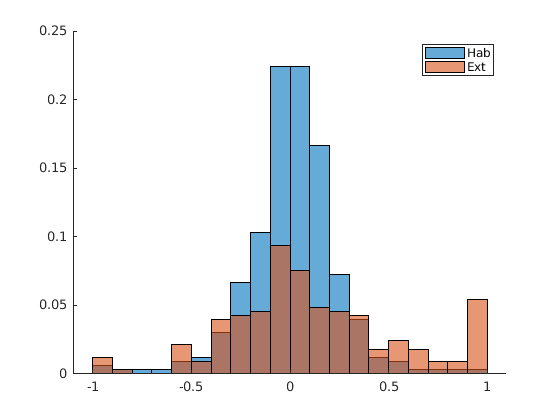

figure,
histogram((FR{1,1}-FR{2,1})./(FR{1,1}+FR{2,1}),[-1:0.1:1],'FaceAlpha',0.6,'Normalization','probability'), hold on
histogram((FR{1,2}-FR{2,2})./(FR{1,2}+FR{2,2}),[-1:0.1:1],'FaceAlpha',0.6,'Normalization','probability')
box off
legend('Hab','Ext')

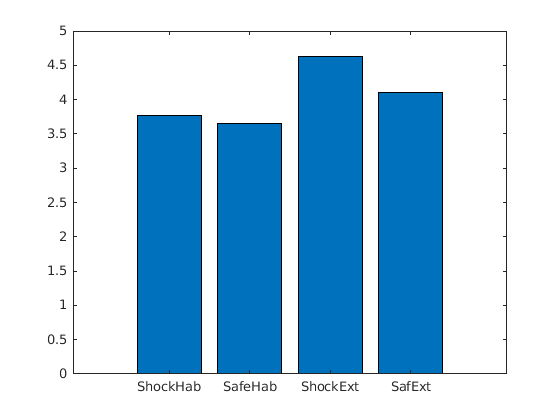

figure
bar(nanmean([FR{1,1};FR{2,1};FR{1,2};FR{2,2}]'))
set(gca,'XTick',[1:4],'XTickLabel',{'ShockHab','SafeHab','ShockExt','SafExt'})

figure
subplot(121)
ModIndexPlot(FR{1,1},FR{2,1})

ans = struct with fields:
    nonparam: 0.0603
       param: 0.2874


title('Hab')
subplot(122)
ModIndexPlot(FR{1,2},FR{2,2})

ans = struct with fields:
    nonparam: 0.0011
       param: 1.0299e-04


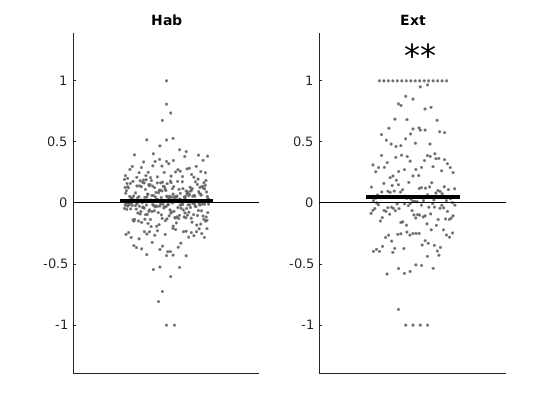

title('Ext')

FR{1,1}=[];
FR{2,2}=[];
FR{2,1}=[];
FR{1,2}=[];
MI{1}=[];
MI{2}=[];
for mouse_num=1:7
    for sp=1:length(EpochFR{mouse_num,1})
        FR{1,1}=[FR{1,1},nanmean(EpochFR{mouse_num,1}(sp).Run.Shock.rand)];
        FR{2,1}=[FR{2,1},nanmean(EpochFR{mouse_num,1}(sp).Run.NoShock.rand)];
        FR{1,2}=[FR{1,2},nanmean(EpochFR{mouse_num,2}(sp).Run.Shock.rand)];
        FR{2,2}=[FR{2,2},nanmean(EpochFR{mouse_num,2}(sp).Run.NoShock.rand)];
        MI{1}=[MI{1},nanmean(EpochFR{mouse_num,1}(sp).Run.Shock_NoShock.rand)];
        MI{2}=[MI{2},nanmean(EpochFR{mouse_num,2}(sp).Run.Shock_NoShock.rand)];
        
    end
end

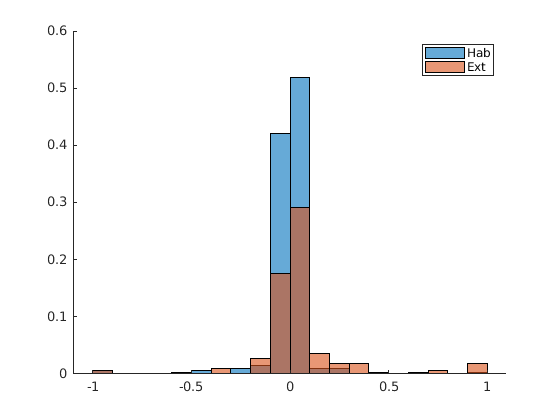

figure,
histogram(MI{1},[-1:0.1:1],'FaceAlpha',0.6,'Normalization','probability'), hold on
histogram(MI{2},[-1:0.1:1],'FaceAlpha',0.6,'Normalization','probability')
box off
legend('Hab','Ext')

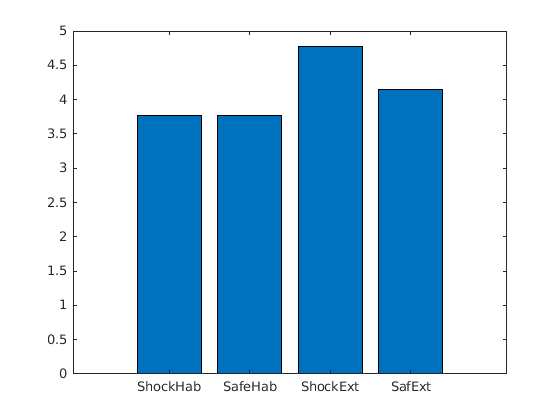

figure
bar(nanmean([FR{1,1};FR{2,1};FR{1,2};FR{2,2}]'))
set(gca,'XTick',[1:4],'XTickLabel',{'ShockHab','SafeHab','ShockExt','SafExt'})


figure
subplot(121)
ModIndexPlot(MI{1},[])

ans = struct with fields:
    nonparam: 0.4427
       param: 0.2204


title('Hab')
subplot(122)
ModIndexPlot(MI{2},[])

ans = struct with fields:
    nonparam: 6.1089e-06
       param: 0.0037


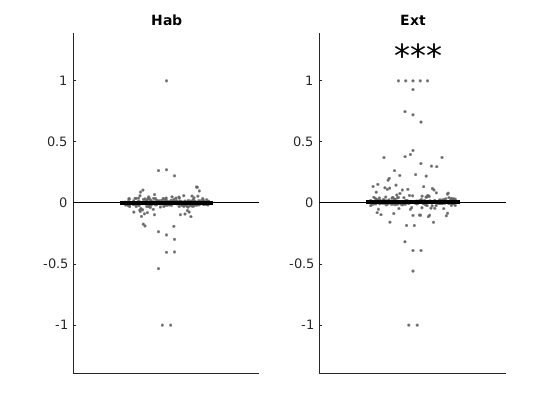

title('Ext')

FR{1,1}=[];
FR{2,2}=[];
FR{2,1}=[];
FR{1,2}=[];
for mouse_num=1:7
    for sp=1:length(EpochFR{mouse_num,1})
        if IsPFCNeuron{mouse_num}(sp)==1
        if abs(EpochFR{mouse_num,1}(sp).Run.Shock_NoShock.IsSig)>0
            % Habituation
            FR{1,1}=[FR{1,1},EpochFR{mouse_num,1}(sp).Run.Shock.real];
            FR{2,1}=[FR{2,1},EpochFR{mouse_num,1}(sp).Run.NoShock.real];
        end
        if abs(EpochFR{mouse_num,2}(sp).Run.Shock_NoShock.IsSig)>0
           % Extinction
            FR{1,2}=[FR{1,2},EpochFR{mouse_num,2}(sp).Run.Shock.real];
            FR{2,2}=[FR{2,2},EpochFR{mouse_num,2}(sp).Run.NoShock.real];
        end
        end
    end
end


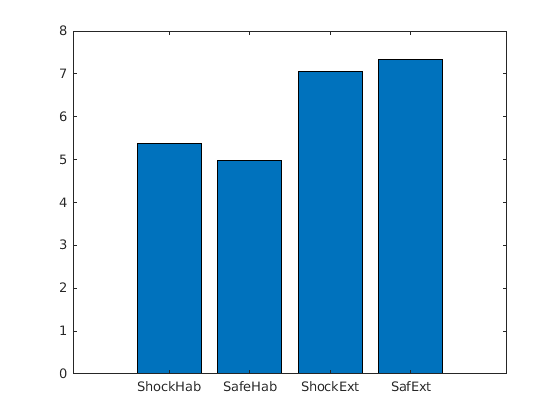

figure
bar(([nanmean(FR{1,1});nanmean(FR{2,1});nanmean(FR{1,2});nanmean(FR{2,2})]'))
set(gca,'XTick',[1:4],'XTickLabel',{'ShockHab','SafeHab','ShockExt','SafExt'})

figure
subplot(121)
ModIndexPlot(FR{1,1},FR{2,1})

ans = struct with fields:
    nonparam: 0.3142
       param: 0.3251


title('Hab')
subplot(122)
ModIndexPlot(FR{1,2},FR{2,2})

ans = struct with fields:
    nonparam: 0.0540
       param: 0.0433


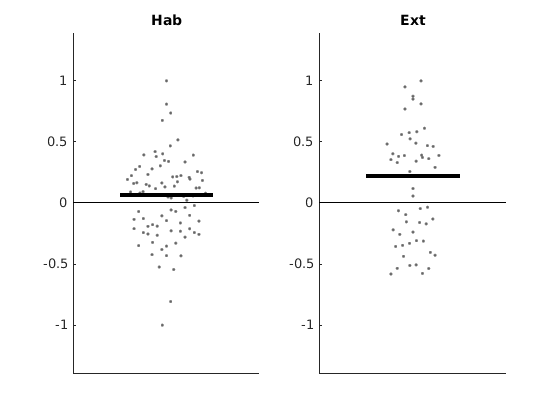

title('Ext')

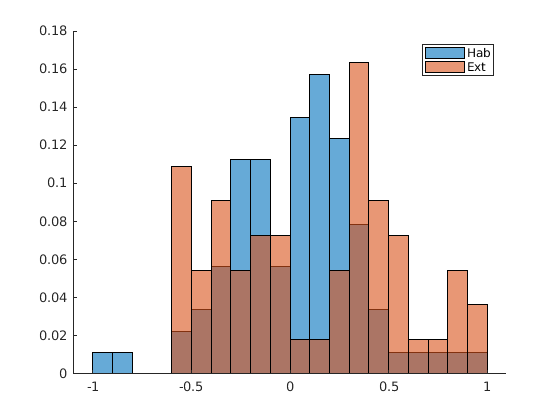

figure,
histogram((FR{1,1}-FR{2,1})./(FR{1,1}+FR{2,1}),[-1:0.1:1],'FaceAlpha',0.6,'Normalization','probability'), hold on
histogram((FR{1,2}-FR{2,2})./(FR{1,2}+FR{2,2}),[-1:0.1:1],'FaceAlpha',0.6,'Normalization','probability')
box off
legend('Hab','Ext')

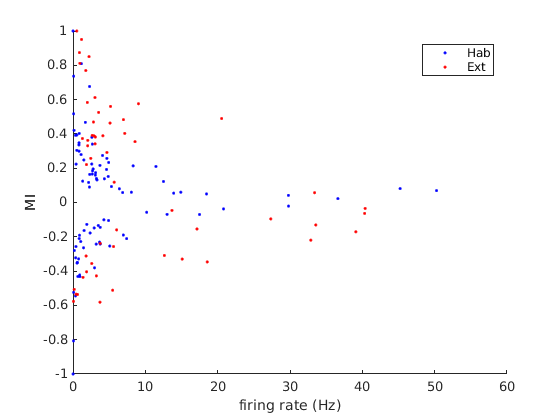

figure,
plot(max([FR{1,1};FR{2,1}]),(FR{1,1}-FR{2,1})./(FR{1,1}+FR{2,1}),'b.'), hold on
plot(max([FR{1,2};FR{2,2}]),(FR{1,2}-FR{2,2})./(FR{1,2}+FR{2,2}),'r.')
box off
xlabel('firing rate (Hz)')
ylabel('MI')
legend('Hab','Ext')